clear all
weatherFileN="STU-60-20241124144111.csv";
files=struct2table(dir)

files = 37×6 table
                    name                                                            folder                                                       date              bytes    isdir     datenum  
    ____________________________________    _______________________________________________________________________________________    ________________________    _____    _____    __________

    {'.'                               }    {'C:\Users\griff\OneDrive\Documents\matlab\Stanford\AA272\Project\Tressider barometer'}    {'05-Dec-2024 23:46:14'}        0    true     7.3959e+05
    {'..'                              }    {'C:\Users\griff\OneDrive\Documents\matlab\Stanford\AA272\Project\Tressider barometer'}    {'05-Dec-2024 18:10:01'}        0    true     7.3959e+05
    {'Pr

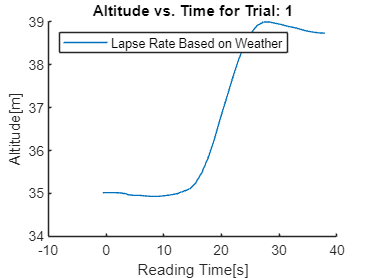

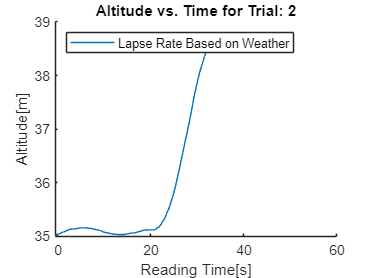

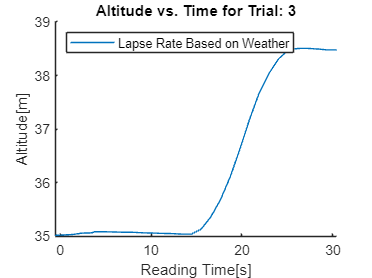

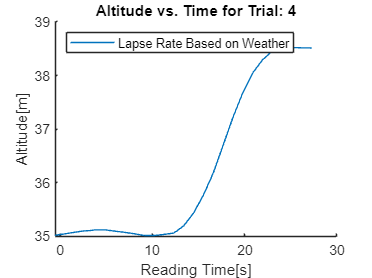

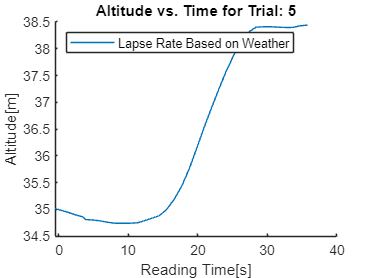

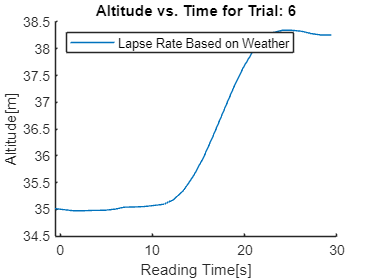

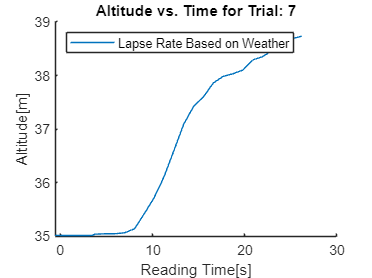

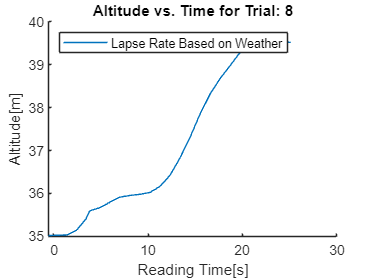

fileList=files.name(3:33);%Will have to adjust based on folder
%UNCOVERED STAIRS
% fileList={
%     'Pressure 2024-11-04 15-40-25.xls',...
%     'Pressure 2024-11-04 15-41-30.xls',...
%     'Pressure 2024-11-04 15-42-39.xls',...
%     'Pressure 2024-11-04 15-43-49.xls',...
%     'Pressure 2024-11-04 15-44-55.xls',...
%     'Pressure 2024-11-04 15-46-14.xls',...
%     'Pressure 2024-11-04 15-47-44.xls',...
%     'Pressure 2024-11-04 15-49-07.xls',...
%     'Pressure 2024-11-04 15-50-24.xls',...
%     'Pressure 2024-11-04 15-51-54.xls',...
%     'Pressure 2024-11-04 15-53-12.xls',...
%     'Pressure 2024-11-04 15-54-28.xls',...
%     'Pressure 2024-11-04 15-55-48.xls',...
%     'Pressure 2024-11-04 15-57-06.xls'
%     };
%approxGroundTruth=19+(174/1000)*19*5+(174/1000)*5;%6th flor plus fron goole map
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


approxGroundTruth=34+4.5212;%178in plus google map altitude

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

endAlts=zeros(length(fileList),1);



for i=1:length(fileList)
    endAlts(i)=totalAltChange(string(fileList(i)),weatherFileN,true,i*137);
end


%STATS SECTION IDEALLY WANT 30+ trials so central limit theroy is more
%applicable
meanAlt=mean(endAlts);
stdAlt=std(endAlts);
approxErrors=approxGroundTruth-endAlts;
meanError=mean(approxErrors);
stdErrors=std(approxErrors);
kstest(approxErrors,'CDF', makedist('Normal', 'mu', meanError, 'sigma', stdErrors))

ans = logical
   0


errorXvalues=[-3*stdErrors+meanError:.01:3*stdErrors+meanError];
dispXValues=[0:.01:approxGroundTruth+3*stdAlt];
figure(111)
yAlt=normpdf(dispXValues,meanAlt,stdAlt);
plot(dispXValues,yAlt)
xlabel("Altitude Gain[m]")
ylabel("Probability Density")
title("PDF of Altitude")
disp("The average Altitude is: "+num2str(meanAlt)+"m")

The average Altitude is: 38.3074m


disp("The standard deviation of the altitude is: "+num2str(stdAlt)+"m")

The standard deviation of the altitude is: 0.36373m


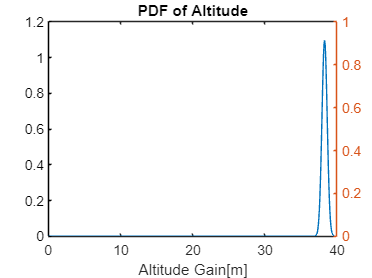

figure(112)
yErr=normpdf(errorXvalues,meanError,stdErrors);
yyaxis left
plot(errorXvalues,yErr)

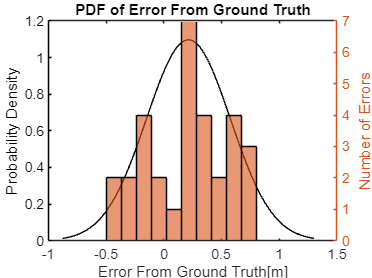

ylabel("Probability Density")
hold on
yyaxis right
histogram(approxErrors,10)
xlabel("Error From Ground Truth[m]")
ylabel("Number of Errors")
title("PDF of Error From Ground Truth")

disp("The average error in altitude is: "+num2str(meanError)+"m")

The average error in altitude is: 0.21376m


disp("The standard deviation of the error is: "+num2str(stdErrors)+"m")

The standard deviation of the error is: 0.36373m


function averageEndAlt=totalAltChange(filename,weatherFileN,plotT,figNum)
    weatherData=readtable(weatherFileN);%Weather Data for Day measurment taken
    data=readtable(filename);%Read Data
    pressures=data.Pressure_hPa_*100;%pressures from phone barometer in Pa
    pressureTimes=data.Time_s_;%Times since start of pressure measurments
    calibrationAltidue=39;%estimated altitude of the stanford weather station from google maps
    %https://www.randymajors.org/elevation-on-google-maps?x=-122.1853021&y=37.4293690&cx=-122.1853719&cy=37.4293179&zoom=17&basemap=hybrid
    %startingUserAlt=19+(174/1000)*19*4+(174/1000)*5;%estimated starting alt from google maps+5thfloor
    startingUserAlt=34+1.016;%estimated starting alt from google maps plus 40 in
    [groundTemp,groundPressure,lbArr]=getWeatherForMeasurment(filename,pressureTimes,weatherData);
    % 
    % figure(figNum+2)
    % plot(pressureTimes,groundPressure)

    lb=-.0065*ones(length(pressures),1);%Standard temperature lapse rate
    R=8.31432;%universal gas constant
    g=9.80665;%Gravity
    M=0.0289644;%Molar mass of air
    absoluetAlt=absoluteAltArr(pressures,groundPressure,groundTemp,lbArr,R,g,M,calibrationAltidue,startingUserAlt);
    if plotT
        figure(figNum)
        hold on
        plot(pressureTimes,absoluetAlt)
        xlabel("Reading Time[s]")
        ylabel("Altitude[m]")
        title("Altitude vs. Time for Trial: "+num2str(figNum/137))
        legend("Lapse Rate Based on Weather",location='northwest')
        hold off
    end
    averageEndAlt=mean(absoluetAlt(end-10:end));
    
end
function deltaAltitudeArray=changeInAltitude(pressure,temperature,lb,R,g,M)
    deltaAltitudeArray=zeros(length(pressure),1);
    p0=pressure(1);
    for i=1:length(temperature)
        deltaAltitudeArray(i)=calculateAlt(p0,pressure(i),0,temperature(i),lb(i),R,g,M);

    end

end

function altitude=calculateAlt(p0,p1,h0,temp,lb,R,g,M)
    %altitude=h0+temp/lb*((p1/p0)^(-R*lb/(g*M))-1);
    altitude=h0+temp/lb*(1-(p1/p0)^(R*lb/(g*M)));
end

function [ambientTemp,ambientPressure,lbMat]=getWeatherForMeasurment(filename,readingTimes,weatherData)
    spaceIndex=strfind(filename," ");%get indecies for spaces in file name
    initTimeStr=string(extractBetween(filename, spaceIndex(end)+1, strfind(filename,".")-1));%Get End time of Measurments
    hour=str2num(extractBefore(initTimeStr,3))*60*60;
    minit=str2num(extractBetween(initTimeStr,4,5))*60;
    sec=str2num(extractAfter(initTimeStr,6));
    endTime=hour+minit+sec;
    startTime=endTime-readingTimes(end);
    ambientPressure=zeros(length(readingTimes),1);
    ambientTemp=zeros(length(readingTimes),1);
    lbMat=zeros(length(readingTimes),1);
    for i=1:length(readingTimes)
        timeFormatted=secondToTime(startTime+readingTimes(i));
        cIndex=find(timeFormatted>weatherData.Time);
        cIndex=cIndex(1);
        %[closestTime, cIndex]=min(abs(weatherData.Time-timeFormatted));
        ambientTemp(i)=(weatherData.Temp__F_(cIndex)-32)*5/9+273.15;
        %ambientPressure(i)=weatherData.Pressure_mb_(cIndex)*100;
        ambientPressure(i)=interpPressure(startTime+readingTimes(i),weatherData.Time(cIndex),weatherData.Time(cIndex-1),weatherData.Pressure_mb_(cIndex),weatherData.Pressure_mb_(cIndex-1))*100;
        lbMat(i)=(((weatherData.Temp10m__F_(cIndex)-32)*5/9+273.15)-((weatherData.Temp2m__F_(cIndex)-32)*5/9+273.15))/(10-2);
    end

end

function closestMin=secondToTime(totalSec)
    h=floor(totalSec / 3600);
    m=floor(mod(totalSec, 3600) / 60);
    s=mod(totalSec, 60);
    closestMin=100*h+m+round(s/60);
end

function adjustedPressure=interpPressure(trueTime,fTime,lTime,fP,lP)
    fSec=floor(fTime / 100)*60*60+mod(fTime,100)*60;
    lSec=floor(lTime / 100)*60*60+mod(lTime,100)*60;
    dt=lSec-fSec;
    dp=lP-fP;
    adjustedPressure=dp/dt*(trueTime-fSec)+fP;


    
end
function absoluteAltArray=absoluteAltArr(phoneP,groundP,temp,lb,R,g,M,groudH,phoneH)
    calibrationP=findCalibration(groudH,phoneH,groundP(1),phoneP(1),temp(1),lb(1),R,g,M);
    phoneP=phoneP+calibrationP;
    absoluteAltArray=zeros(length(phoneP),1);
    for i=1:length(absoluteAltArray)
        absoluteAltArray(i)=calculateAlt(groundP(i),phoneP(i),groudH,temp(i),lb(i),R,g,M);
    end
    
    
end

function caliConstant=findCalibration(refrenceAlt, phoneAlt, refrenceP,phoneP,temperature,lb,R,g,M)
    theoP=refrenceP*(1-lb/temperature*(phoneAlt-refrenceAlt))^(g*M/(R*lb));
    caliConstant=theoP-phoneP;
end
